# SUMMARY OF TESTS

## Tchebychev polynomials

x = -1:0.01:1;
X=meshgrid(x,x);
Y=-X';
%% Les résultats sont à comparés avec la fonction de la bibliothèque 
%% matlab [t] = tchebychev_polyXY(2,X,1)

counter=1;Xind=zeros(1,5151);Yind=zeros(1,5151);
for i=0:100
    for j=0:i
        Xind(counter)=i-j;
        Yind(counter)=j;
        counter=counter+1;
    end
end
n=linspace(1,8,8);
% m=zeros(1,max(n))
T=zeros(length(n),length(X(:)));
%2Dfy it
for i=1:length(n)
    Mat = tchebychev_polyXY(Xind(n(i)),X,1).* tchebychev_polyXY(Yind(n(i)),Y,2);
    T(i,:)=Mat(:);
%     m(i)=norm(T(i,:));
%     T(i,:)=T(i,:)/m(i);
end

T8=reshape(T(8,:),[201,201])

T8 =     1.0000    0.9602    0.9208    0.8818    0.8432    0.8050    0.7672    0.7298    0.6928    0.6562    0.6200    0.5842    0.5488    0.5138    0.4792    0.4450    0.4112    0.3778    0.3448    0.3122    0.2800    0.2482    0.2168    0.1858    0.1552    0.1250    0.0952    0.0658    0.0368    0.0082   -0.0200   -0.0478   -0.0752   -0.1022   -0.1288   -0.1550   -0.1808   -0.2062   -0.2312   -0.2558   -0.2800   -0.3038   -0.3272   -0.3502   -0.3728   -0.3950   -0.4168   -0.4382   -0.4592   -0.4798
    0.9900    0.9506    0.9116    0.8730    0.8348    0.7969    0.7595    0.7225    0.6859    0.6496    0.6138    0.5784    0.5433    0.5087    0.4744    0.4405    0.4071    0.3740    0.3414    0.3091    0.2772    0.2457    0.2146    0.1839    0.1536    0.1237    0.0942    0.0651    0.0364    0.0081   -0.0198   -0.0473   -0.0744   -0.1012   -0.1275   -0.1534   -0.1790   -0.2041   -0.2289   -0.2532   -0.2772   -0.3008   -0.3239   -0.3467   -0.3691   -0.3911   -0.4126   -0.4338   -0.4546   -

T7=reshape(T(7,:),[201,201])

T7 =    -1.0000   -0.9112   -0.8248   -0.7407   -0.6589   -0.5795   -0.5023   -0.4274   -0.3548   -0.2843   -0.2160   -0.1499   -0.0859   -0.0240    0.0358    0.0935    0.1492    0.2029    0.2545    0.3042    0.3520    0.3978    0.4418    0.4839    0.5241    0.5625    0.5991    0.6339    0.6670    0.6984    0.7280    0.7560    0.7823    0.8069    0.8300    0.8515    0.8714    0.8898    0.9067    0.9221    0.9360    0.9485    0.9596    0.9692    0.9775    0.9845    0.9901    0.9945    0.9976    0.9994
   -1.0000   -0.9112   -0.8248   -0.7407   -0.6589   -0.5795   -0.5023   -0.4274   -0.3548   -0.2843   -0.2160   -0.1499   -0.0859   -0.0240    0.0358    0.0935    0.1492    0.2029    0.2545    0.3042    0.3520    0.3978    0.4418    0.4839    0.5241    0.5625    0.5991    0.6339    0.6670    0.6984    0.7280    0.7560    0.7823    0.8069    0.8300    0.8515    0.8714    0.8898    0.9067    0.9221    0.9360    0.9485    0.9596    0.9692    0.9775    0.9845    0.9901    0.9945    0.9976    


%% test d'orthogonalité
sqrt(dot(T,T))

ans =     2.8284    2.8040    2.7801    2.7569    2.7342    2.7121    2.6906    2.6697    2.6494    2.6296    2.6104    2.5918    2.5738    2.5563    2.5394    2.5230    2.5072    2.4919    2.4771    2.4629    2.4492    2.4360    2.4233    2.4111    2.3994    2.3881    2.3774    2.3671    2.3572    2.3478    2.3389    2.3304    2.3223    2.3146    2.3072    2.3003    2.2938    2.2876    2.2818    2.2763    2.2712    2.2664    2.2619    2.2577    2.2538    2.2502    2.2469    2.2438    2.2410    2.2384


mean(T8,"all")

ans = 1.5581e-18

mean(T7,"all")

ans = 2.8421e-16

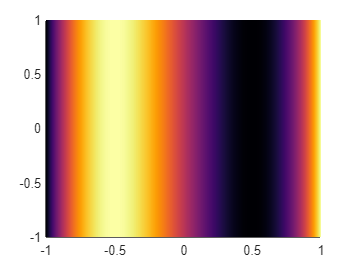


figure
pcolor(X,Y,T7), shading interp

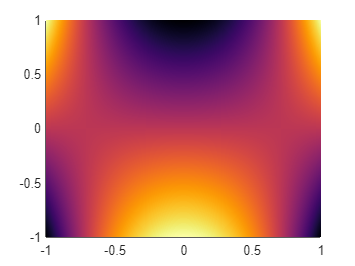

figure
pcolor(X,Y,T8), shading interp


%%comparaison avec 
[T2,Xind,Yind] = Legendre2D(n,X,Y);
Tnew2=reshape(T2(8,:),[201,201])

Tnew2 =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9900    0.9604    0.9312    0.9022    0.8736    0.8452    0.8171    0.7894    0.7619    0.7347    0.7078    0.6813    0.6550    0.6290    0.6033    0.5779    0.5528    0.5280    0.5035    0.4793    0.4554    0.4318    0.4085    0.3855    0.3627    0.3403    0.3182    0.2964    0.2748    0.2536    0.2326    0.2120    0.1917    0.1716    0.1519    0.1324    0.1133    0.0944    0.0758    0.0576    0.0396    0.0219    0.0046   -0.0125   -0.0293   -0.0458   -0.0620   -0.0779   -0.0935 

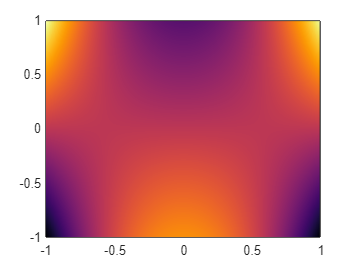

figure
pcolor(X,Y,Tnew2), shading interp


% read_opd("Flat1_CPC_PH72_OptimiseAvecFocus.Opd")

2D polynomial results are similar to those we obtain with Legendre. Then we can move to the next step of projection

% carte=read_opd("cartes\Flat1_CPC_PH72_OptimiseAvecFocus.Opd");
% n=linspace(1,36,36)
% [a,T,res]=TchebychevDecomposeMap(carte,n)

The projection applied for a number of 36 orders is working fine.

The next step is the integration of the code into the app designer.

x = -1:0.01:1;
X=meshgrid(x,x);
Y=-X';
n=linspace(1,5,5);
J= jacobiP(2,2,5,X)

J =    21.0000   20.6514   20.3055   19.9624   19.6220   19.2844   18.9495   18.6174   18.2880   17.9614   17.6375   17.3164   16.9980   16.6824   16.3695   16.0594   15.7520   15.4474   15.1455   14.8464   14.5500   14.2564   13.9655   13.6774   13.3920   13.1094   12.8295   12.5524   12.2780   12.0064   11.7375   11.4714   11.2080   10.9474   10.6895   10.4344   10.1820    9.9324    9.6855    9.4414    9.2000    8.9614    8.7255    8.4924    8.2620    8.0344    7.8095    7.5874    7.3680    7.1514
   21.0000   20.6514   20.3055   19.9624   19.6220   19.2844   18.9495   18.6174   18.2880   17.9614   17.6375   17.3164   16.9980   16.6824   16.3695   16.0594   15.7520   15.4474   15.1455   14.8464   14.5500   14.2564   13.9655   13.6774   13.3920   13.1094   12.8295   12.5524   12.2780   12.0064   11.7375   11.4714   11.2080   10.9474   10.6895   10.4344   10.1820    9.9324    9.6855    9.4414    9.2000    8.9614    8.7255    8.4924    8.2620    8.0344    7.8095    7.5874    7.3680    7